%setup add MatNWB to path

% path to file - will change
folder = '/Users/cesar/DANDIsets/000017/sub-Moniz';
filepath = [folder '/' 'sub-Moniz_ses-20170515T120000.nwb'];
% read in file
nwb_file = nwbRead(filepath);

ntrials = length(nwb_file.intervals_trials.start_time.data(:));
fprintf('Total trials: %d\n', ntrials)

Total trials: 247


% select trial
trial = 10;

% print trial info
info = getTrialInfo(nwb_file, trial);

fprintf('Stimulus Contrast Left: %.02f || Right: %.02f\n', ...
    info.stim_contrast_left, ...
    info.stim_contrast_right)

Stimulus Contrast Left: 0.00 || Right: 0.50


fprintf('Animal Choice: %s \n',info.response_choice)

Animal Choice: Left 


fprintf('Feedback: %s \n',info.feedback_type)

Feedback: Punishment 


fprintf('Reaction Time: %.02f \n',info.response_time)

Reaction Time: 1.62 


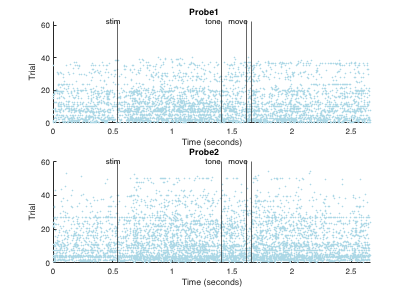

% output raster plot figure
plotRastersAllUnits(nwb_file, trial)